# Processing EMG data

clear

## Marks per movement

1.3 -> Move thumb 101

2.3 -> Move index 102

3.3 -> Move middle 103

4.3 -> Move ring 104

5 .3 -> Move pinky 105

6 .3 -> Make a fist 106

Fixation 1

Relax 200

## Format the data of the ebr file

Dont forget to change filename and variable to save the

data correctly

% Which subject
sujeto = 'S16';

% Check if folder of the subject exists
if ~exist(sujeto, 'dir')
    % Create if it does not
    mkdir(sujeto)
end

% Search for ebr file of the subject
% C:\Users\yelil\OneDrive\Documentos\GitHub\HoH_Controller\Matlab\EBR_data
location = "C:\Users\jmfig\OneDrive\Escritorio\Matlab_S7\ReadData\EBR_DATA\";
filename = strcat(location,sujeto,'.ebr');
% Change .ebr data to struct
emgdata = loadEEGData(filename);
% Get length
len = length(emgdata.data);
% Channels used in experiment
channels = 4;

% Initial variables
% Discriminate raw data, timestamp and marks 
raw_dataCh1 = emgdata.data(:,(1:8));
timestamp = emgdata.data(:,9);
marks = emgdata.data(:,10);

raw_data = emgdata.data(:,(2:2:8));

## Plot raw_data and marks to understand

% figure
% plot(timestamp,raw_dataCh1(:,2)); xlabel('timestamp'); ylabel('raw data');
% hold on
% plot(timestamp, marks, 'r'); xlabel('timestamp'); ylabel('marks');
% title('CH1 signal x marks')
% hold off

## Plot raw signal from Ch1

% plot(timestamp,raw_dataCh1(:,1)); xlabel('timestamp'); ylabel('raw data');

## Get markers positions

% Find marks from the experiment, their values and indexes
[pks, locs] = findpeaks(marks);

% Trials done in experiment
trials = (length(pks)/3)/6;
tot_trials = trials*6;

## Get windows

% Create a 3D matrix
samples = 2624;
info = zeros(samples,4,tot_trials); %timexchannelxtrial of every movement
% Matrix per movement
thumb = zeros(samples,4,trials);
index = zeros(samples,4,trials);
middle = zeros(samples,4,trials);
ring = zeros(samples,4,trials);
pinky = zeros(samples,4,trials);
hand = zeros(samples,4,trials);

% Check if all trial have been read
% Add them to info matrix move-position (3 dimension)
trial = 0;
thumb_count = 0;
index_count = 0;
middle_count = 0;
ring_count = 0;
pinky_count = 0;
hand_count = 0;

% Check each mark and add to matrix if it is
% a finger movement
% Get 4 channels only because of bipolarity
for i=1:length(pks)
    % Check the marks and add them to the movement matrix
        % thumb
    if(pks(i)==101) % thumb mark in experiment is 101
        trial = trial + 1;
        thumb_count = thumb_count + 1;
        mov1 = zeros(2624,4);
        % add each movement to info matrix
        mov1(:,1)= emgdata.data(locs(i):locs(i)+samples-1,2);
        mov1(:,2)= emgdata.data(locs(i):locs(i)+samples-1,4);
        mov1(:,3)= emgdata.data(locs(i):locs(i)+samples-1,6);
        mov1(:,4)= emgdata.data(locs(i):locs(i)+samples-1,8);
        info(:,:,trial) = mov1;
        thumb(:,:,thumb_count) = mov1(:,:);

        % index
    elseif(pks(i)==102)
        mov2 = zeros(samples,4);
        trial = trial + 1;
        index_count = index_count + 1;
        % add 4 channels to index movement
        % add each movement to info matrix
        mov2(:,1)= emgdata.data(locs(i):locs(i)+samples-1,2);
        mov2(:,2)= emgdata.data(locs(i):locs(i)+samples-1,4);
        mov2(:,3)= emgdata.data(locs(i):locs(i)+samples-1,6);
        mov2(:,4)= emgdata.data(locs(i):locs(i)+samples-1,8);
        info(:,:,trial) = mov2;
        index(:,:,index_count) = mov2(:,:);

        % middle
    elseif(pks(i)==103)
        mov3 = zeros(samples,4);
        trial = trial + 1;
        middle_count = middle_count + 1;
        % add 4 channels to movement
        % add each movement to info matrix
        mov3(:,1)= emgdata.data(locs(i):locs(i)+samples-1,2);
        mov3(:,2)= emgdata.data(locs(i):locs(i)+samples-1,4);
        mov3(:,3)= emgdata.data(locs(i):locs(i)+samples-1,6);
        mov3(:,4)= emgdata.data(locs(i):locs(i)+samples-1,8);
        info(:,:,trial) = mov3;
        middle(:,:,middle_count) = mov3(:,:);

        % ring
    elseif(pks(i)==104)
        mov4 = zeros(samples,4);
        trial = trial + 1;
        ring_count = ring_count + 1;
        % add 4 channels to ring movement
        % add each movement to info matrix
        mov4(:,1)= emgdata.data(locs(i):locs(i)+samples-1,2);
        mov4(:,2)= emgdata.data(locs(i):locs(i)+samples-1,4);
        mov4(:,3)= emgdata.data(locs(i):locs(i)+samples-1,6);
        mov4(:,4)= emgdata.data(locs(i):locs(i)+samples-1,8);
        info(:,:,trial) = mov4;
        ring(:,:,ring_count) = mov4(:,:);

        % pinky
    elseif(pks(i)==105)
        mov5 = zeros(samples,4);
        trial = trial + 1;
        pinky_count = pinky_count + 1;
        % add 4 channels to pinky movement
        % add each movement to info matrix
        mov5(:,1)= emgdata.data(locs(i):locs(i)+samples-1,2);
        mov5(:,2)= emgdata.data(locs(i):locs(i)+samples-1,4);
        mov5(:,3)= emgdata.data(locs(i):locs(i)+samples-1,6);
        mov5(:,4)= emgdata.data(locs(i):locs(i)+samples-1,8);
        info(:,:,trial) = mov5;
        pinky(:,:,pinky_count) = mov5(:,:);

        % full hand
    elseif(pks(i)==106)
        mov6 = zeros(samples,4);
        trial = trial + 1;
        hand_count = hand_count + 1;
        % add 4 channels to full hand movement 2599-300
        % add each movement to info matrix
        mov6(:,1)= emgdata.data(locs(i)-400:locs(i)+samples-401,2);
        mov6(:,2)= emgdata.data(locs(i)-400:locs(i)+samples-401,4);
        mov6(:,3)= emgdata.data(locs(i)-400:locs(i)+samples-401,6);
        mov6(:,4)= emgdata.data(locs(i)-400:locs(i)+samples-401,8);
        info(:,:,trial) = mov6;
        hand(:,:,hand_count) = mov6(:,:);

    end
end

trial = 6

trial = 12

trial = 18

trial = 24

trial = 30

trial = 36

trial = 42

trial = 48

trial = 54

trial = 60

trial = 66

trial = 72

trial = 78

trial = 84

trial = 90

trial = 96

trial = 102

trial = 108

trial = 114

trial = 120

trial = 126

trial = 132

trial = 138

trial = 144

trial = 150

trial = 156

trial = 162

trial = 168

trial = 174

trial = 180

trial = 186

trial = 192

trial = 198

trial = 204

trial = 210

trial = 216

trial = 222

trial = 228

trial = 234

trial = 240

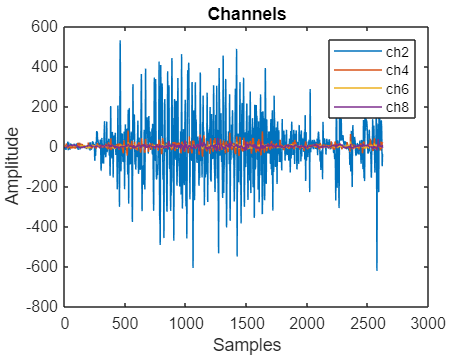


% Plot data
trial = 1;
plot(info(:,:,1))
title('Channels')
legend('ch2','ch4','ch6','ch8')
xlabel('Samples')
ylabel('Amplitude')


% Save into mat file matrix information
% savelocation = strcat(sujeto,'/',sujeto,'info.mat');
% save(savelocation,"info");
% savelocation = strcat(sujeto,'/',sujeto,'thumb.mat');
% save(savelocation,"thumb");
% savelocation = strcat(sujeto,'/',sujeto,'index.mat');
% save(savelocation,"index");
% savelocation = strcat(sujeto,'/',sujeto,'middle.mat');
% save(savelocation,"middle");
% savelocation = strcat(sujeto,'/',sujeto,'ring.mat');
% save(savelocation,"ring");
% savelocation = strcat(sujeto,'/',sujeto,'pinky.mat');
% save(savelocation,"pinky");

## Base Line

% Apply baseline for initial preprocessing
bl = zeros(samples,4,tot_trials);
bl1 = zeros(samples,4,trials);
bl2 = zeros(samples,4,trials);
bl3 = zeros(samples,4,trials);
bl4 = zeros(samples,4,trials);
bl5 = zeros(samples,4,trials);
bl6 = zeros(samples,4,trials);

% Base Line for all the info matrix
for i=1:length(info(1,:,:))
    bl(:,:,i) = info(:,:,i) - mean(info(:,:,i));
end

% Base Line per movement
for i=1:trials
    bl1(:,:,i) = thumb(:,:,i) - mean(thumb(:,:,i));
    bl2(:,:,i) = index(:,:,i) - mean(index(:,:,i));
    bl3(:,:,i) = middle(:,:,i) - mean(middle(:,:,i));
    bl4(:,:,i) = ring(:,:,i) - mean(ring(:,:,i));
    bl5(:,:,i) = pinky(:,:,i) - mean(pinky(:,:,i));
    bl6(:,:,i) = hand(:,:,i) - mean(hand(:,:,i));
end

% Plot base line
% figure;
% plot(bl(:,:,1))
% title('Base Line')
% legend('ch2','ch4','ch6','ch8')

# Obtaining Data

EMV (Envelope Maximum Value)

RMS (Root Mean Squeare)

VAR (Variance)

STD (Standar Deviation)

MAV (Maximum Absolute Value)

AUC (Area Under the Curve)

IEMG (Integrated EMG)

LOGD (Log Detector)

ZCR (Zero Crossing)

WFL (Wave Form Length)

SSI (Simple Squared Integral)

WEN (Wavelet Entropy)

% EMV
thumb_emv = zeros(trials,4); %trial x channels x move
index_emv = zeros(trials,4); %trial x channels x move
middle_emv = zeros(trials,4); %trial x channels x move
ring_emv = zeros(trials,4); %trial x channels x move
pinky_emv = zeros(trials,4); %trial x channels x move
hand_emv = zeros(trials,4); %trial x channels x move

% RMS
thumb_rms = zeros(trials,4); %trial x channels x move
index_rms = zeros(trials,4); %trial x channels x move
middle_rms = zeros(trials,4); %trial x channels x move
ring_rms = zeros(trials,4); %trial x channels x move
pinky_rms = zeros(trials,4); %trial x channels x move
hand_rms = zeros(trials,4); %trial x channels x move

% VAR
thumb_var = zeros(trials,4); %trial x channels x move
index_var = zeros(trials,4); %trial x channels x move
middle_var = zeros(trials,4); %trial x channels x move
ring_var = zeros(trials,4); %trial x channels x move
pinky_var = zeros(trials,4); %trial x channels x move
hand_var = zeros(trials,4); %trial x channels x move

% STD
thumb_std = zeros(trials,4); %trial x channels x move
index_std = zeros(trials,4); %trial x channels x move
middle_std = zeros(trials,4); %trial x channels x move
ring_std = zeros(trials,4); %trial x channels x move
pinky_std = zeros(trials,4); %trial x channels x move
hand_std = zeros(trials,4); %trial x channels x move

% MAV
thumb_mav = zeros(trials,4); %trial x channels x move
index_mav = zeros(trials,4); %trial x channels x move
middle_mav = zeros(trials,4); %trial x channels x move
ring_mav = zeros(trials,4); %trial x channels x move
pinky_mav = zeros(trials,4); %trial x channels x move
hand_mav = zeros(trials,4); %trial x channels x move

% AUC
thumb_auc = zeros(trials,4); %trial x channels x move
index_auc = zeros(trials,4); %trial x channels x move
middle_auc = zeros(trials,4); %trial x channels x move
ring_auc = zeros(trials,4); %trial x channels x move
pinky_auc = zeros(trials,4); %trial x channels x move
hand_auc = zeros(trials,4); %trial x channels x move

% IEMG
thumb_iemg = zeros(trials,4); %trial x channels x move
index_iemg = zeros(trials,4); %trial x channels x move
middle_iemg = zeros(trials,4); %trial x channels x move
ring_iemg = zeros(trials,4); %trial x channels x move
pinky_iemg = zeros(trials,4); %trial x channels x move
hand_iemg = zeros(trials,4); %trial x channels x move

% LOGD
thumb_logd = zeros(trials,4); %trial x channels x move
index_logd = zeros(trials,4); %trial x channels x move
middle_logd = zeros(trials,4); %trial x channels x move
ring_logd = zeros(trials,4); %trial x channels x move
pinky_logd = zeros(trials,4); %trial x channels x move
hand_logd = zeros(trials,4); %trial x channels x move

% ZCR
thumb_zcr = zeros(trials,4); %trial x channels x move
index_zcr = zeros(trials,4); %trial x channels x move
middle_zcr = zeros(trials,4); %trial x channels x move
ring_zcr = zeros(trials,4); %trial x channels x move
pinky_zcr = zeros(trials,4); %trial x channels x move
hand_zcr = zeros(trials,4); %trial x channels x move

% WFl
thumb_wfl = zeros(trials,4); %trial x channels x move
index_wfl = zeros(trials,4); %trial x channels x move
middle_wfl = zeros(trials,4); %trial x channels x move
ring_wfl = zeros(trials,4); %trial x channels x move
pinky_wfl = zeros(trials,4); %trial x channels x move
hand_wfl = zeros(trials,4); %trial x channels x move

% SSI
thumb_ssi = zeros(trials,4); %trial x channels x move
index_ssi = zeros(trials,4); %trial x channels x move
middle_ssi = zeros(trials,4); %trial x channels x move
ring_ssi = zeros(trials,4); %trial x channels x move
pinky_ssi = zeros(trials,4); %trial x channels x move
hand_ssi = zeros(trials,4); %trial x channels x move

% WEN
thumb_wen = zeros(trials,4); %trial x channels x move
index_wen = zeros(trials,4); %trial x channels x move
middle_wen = zeros(trials,4); %trial x channels x move
ring_wen = zeros(trials,4); %trial x channels x move
pinky_wen = zeros(trials,4); %trial x channels x move
hand_wen = zeros(trials,4); %trial x channels x move

for i=1:channels % for every channel
    for j=1:trials % for every trial
        % ----- THUMB ------
            % EMV
        emv = envelope(bl1(:,i,j),80,'peaks');
        thumb_emv(j,i) = max(emv);
            % RMS
        thumb_rms(j,i) = rms(bl1(:,i,j));
            % VAR
        thumb_var(j,i) = var(bl1(:,i,j));
            % STD
        thumb_std(j,i) = std(bl1(:,i,j));
            % MAV
        thumb_mav(j,i) = maxabs(bl1(:,i,j));
            % AUC
        thumb_auc(j,i) = trapz(emv);
            % IEMG
        thumb_iemg(j,i) = jIntegratedEMG(bl1(:,i,j));
            % LOGD
        thumb_logd(j,i) = jLogDetector(bl1(:,i,j));
            % ZCR
        thumb_zcr(j,i) = jZeroCrossing(bl1(:,i,j),0);
            % WFL
        thumb_wfl(j,i) = jWaveformLength(bl1(:,i,j));
            % SSI
        thumb_ssi(j,i) = jSimpleSquareIntegral(bl1(:,i,j));
            % WEN
        thumb_wen(j,i) = wentropy(bl1(:,i,j),'shannon');

        % ----- INDEX -----
            % EMV
        emv = envelope(bl2(:,i,j),80,'peaks');
        index_emv(j,i) = max(emv);
            % RMS
        index_rms(j,i) = rms(bl2(:,i,j));
            % VAR
        index_var(j,i) = var(bl2(:,i,j));
            % STD 
        index_std(j,i) = std(bl2(:,i,j));
            % MAV
        index_mav(j,i) = maxabs(bl2(:,i,j));
            % AUC
        index_auc(j,i) = trapz(emv);
            % IEMG
        index_iemg(j,i) = jIntegratedEMG(bl2(:,i,j));
            % LOGD
        index_logd(j,i) = jLogDetector(bl2(:,i,j));
            % ZCR
        index_zcr(j,i) = jZeroCrossing(bl2(:,i,j),0);
            % WFL
        index_wfl(j,i) = jWaveformLength(bl2(:,i,j));
            % SSI
        index_ssi(j,i) = jSimpleSquareIntegral(bl2(:,i,j));
            % WEN
        index_wen(j,i) = wentropy(bl2(:,i,j),'shannon');
        
        % ----- MIDDLE -----
            % EMV
        emv = envelope(bl3(:,i,j),80,'peaks');
        middle_emv(j,i) = max(emv);
            % RMS
        middle_rms(j,i) = rms(bl3(:,i,j));
            % VAR
        middle_var(j,i) = var(bl3(:,i,j));
            % STD
        middle_std(j,i) = std(bl3(:,i,j));
            % MAV
        middle_mav(j,i) = maxabs(bl3(:,i,j));
            % AUC
        middle_auc(j,i) = trapz(emv);
            % IEMG
        middle_iemg(j,i) = jIntegratedEMG(bl3(:,i,j));
            % LOGD
        middle_logd(j,i) = jLogDetector(bl3(:,i,j));
            % ZCR
        middle_zcr(j,i) = jZeroCrossing(bl3(:,i,j),0);
            % WFL
        middle_wfl(j,i) = jWaveformLength(bl3(:,i,j));
            % SSI
        middle_ssi(j,i) = jSimpleSquareIntegral(bl3(:,i,j));
            % WEN
        middle_wen(j,i) = wentropy(bl3(:,i,j),'shannon');

        % ----- RING -----
            % EMV
        emv = envelope(bl4(:,i,j),80,'peaks');
        ring_emv(j,i) = max(emv);
            % RMS
        ring_rms(j,i) = rms(bl4(:,i,j));
            % VAR 
        ring_var(j,i) = var(bl4(:,i,j));
            % STD
        ring_std(j,i) = std(bl4(:,i,j));
            % MAV
        ring_mav(j,i) = maxabs(bl4(:,i,j));
            % AUC
        ring_auc(j,i) = trapz(emv);
            % IEMG
        ring_iemg(j,i) = jIntegratedEMG(bl4(:,i,j));
            % LOGD
        ring_logd(j,i) = jLogDetector(bl4(:,i,j));
            % ZCR
        ring_zcr(j,i) = jZeroCrossing(bl4(:,i,j),0);
            % WFL
        ring_wfl(j,i) = jWaveformLength(bl4(:,i,j));
            % SSI
        ring_ssi(j,i) = jSimpleSquareIntegral(bl4(:,i,j));
            % WEN
        ring_wen(j,i) = wentropy(bl4(:,i,j),'shannon');

        % ----- PINKY -----
            % EMV
        emv = envelope(bl5(:,i,j),80,'peaks');
        pinky_emv(j,i) = max(emv);
            % RMS 
        pinky_rms(j,i) = rms(bl5(:,i,j));
            % VAR
        pinky_var(j,i) = var(bl5(:,i,j));
            % STD
        pinky_std(j,i) = std(bl5(:,i,j));
            % MAV
        pinky_mav(j,i) = maxabs(bl5(:,i,j));
            % IEMG
        pinky_iemg(j,i) = jIntegratedEMG(bl5(:,i,j));
            % AUC
        pinky_auc(j,i) = trapz(emv);
            % LOGD
        pinky_logd(j,i) = jLogDetector(bl5(:,i,j));
            % ZCR
        pinky_zcr(j,i) = jZeroCrossing(bl5(:,i,j),0);
            % WFL
        pinky_wfl(j,i) = jWaveformLength(bl5(:,i,j));
            % SSI
        pinky_ssi(j,i) = jSimpleSquareIntegral(bl5(:,i,j));
            % WEN
        pinky_wen(j,i) = wentropy(bl5(:,i,j),'shannon');

        % ----- HAND -----
            % EMV
        emv = envelope(bl6(:,i,j),80,'peaks');
        hand_emv(j,i) = max(emv);
            % RMS
        hand_rms(j,i) = rms(bl6(:,i,j));
            % VAR
        hand_var(j,i) = var(bl6(:,i,j));
            % STD
        hand_std(j,i) = std(bl6(:,i,j));
            % MAV
        hand_mav(j,i) = maxabs(bl6(:,i,j));
            % AUC
        hand_auc(j,i) = trapz(emv);
            % IEMG
        hand_iemg(j,i) = jIntegratedEMG(bl6(:,i,j));
            % LOGD
        hand_logd(j,i) = jLogDetector(bl6(:,i,j));
            % ZCR
        hand_zcr(j,i) = jZeroCrossing(bl6(:,i,j),0);
            % WFL
        hand_wfl(j,i) = jWaveformLength(bl6(:,i,j));
            % SSI
        hand_ssi(j,i) = jSimpleSquareIntegral(bl6(:,i,j));
            % WEN
        hand_wen(j,i) = wentropy(bl6(:,i,j),'shannon');

    end  
end

## Box plot EMV

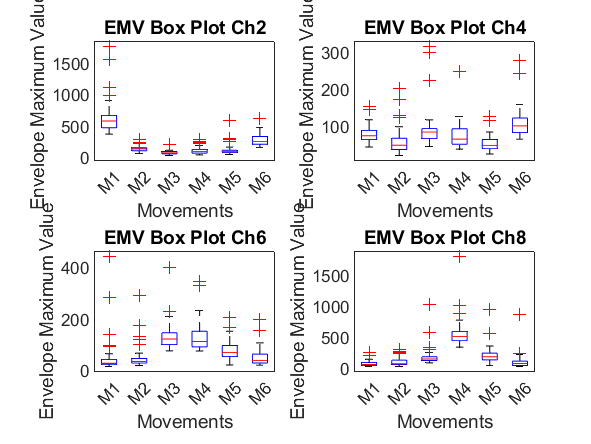

figure;
PBperChMethod(thumb_emv,index_emv,middle_emv,ring_emv,pinky_emv,hand_emv, ...
    'Envelope Maximum Value', ...
    'EMV', ...
    sujeto)

## Box plot RMS

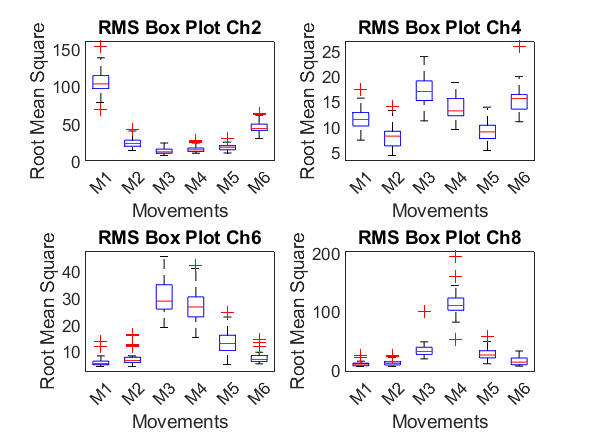

PBperChMethod(thumb_rms,index_rms,middle_rms,ring_rms,pinky_rms,hand_rms, ...
    'Root Mean Square', ...
    'RMS', ...
    sujeto)

## Box plot VAR

% PBperChMethod(thumb_var,index_var,middle_var,ring_var,pinky_var,hand_var, ...
%     'Varianza', ...
%     'VAR', ...
%     sujeto)

## Box plot STD

% PBperChMethod(thumb_std,index_std,middle_std,ring_std,pinky_std,hand_std, ...
%     'Standard Deviation', ...
%     'STD', ...
%     sujeto)

## Box plot MAV

% PBperChMethod(thumb_mav,index_mav,middle_mav,ring_mav,pinky_mav,hand_mav, ...
%     'Mean Absolute Value', ...
%     'MAV', ...
%     sujeto)

## Box plot AUC

% PBperChMethod(thumb_auc,index_auc,middle_auc,ring_auc,pinky_auc,hand_auc, ...
%     'Area Under the Curve', ...
%     'AUC', ...
%     sujeto)

## Box plot IEMG

% PBperChMethod(thumb_iemg,index_iemg,middle_iemg,ring_iemg,pinky_iemg,hand_iemg, ...
%     'Integrated EMG', ...
%     'IEMG', ...
%     sujeto)

## Box plot LOGD

% PBperChMethod(thumb_logd,index_logd,middle_logd,ring_logd,pinky_logd,hand_logd, ...
%     'Logarithmic Detector', ...
%     'LOGD', ...
%     sujeto)

## Box plot ZCR

% PBperChMethod(thumb_zcr,index_zcr,middle_zcr,ring_zcr,pinky_zcr,hand_zcr, ...
%     'Zero Crossing', ...
%     'ZCR', ...
%     sujeto)

## Box plot WFL

% PBperChMethod(thumb_wfl,index_wfl,middle_wfl,ring_wfl,pinky_wfl,hand_wfl, ...
%     'Wave Form Length', ...
%     'WFL', ...
%     sujeto)

## Box plot SSI

% PBperChMethod(thumb_ssi,index_ssi,middle_ssi,ring_ssi,pinky_ssi,hand_ssi, ...
%     'Simple Square Integral', ...
%     'SSI', ...
%     sujeto)

## Box plot WEN

% PBperChMethod(thumb_wen,index_wen,middle_wen,ring_wen,pinky_wen,hand_wen, ...
%     'Wavelet Entropy', ...
%     'WEN', ...
%     sujeto)

# PSD Analisis

## PSD Understanding

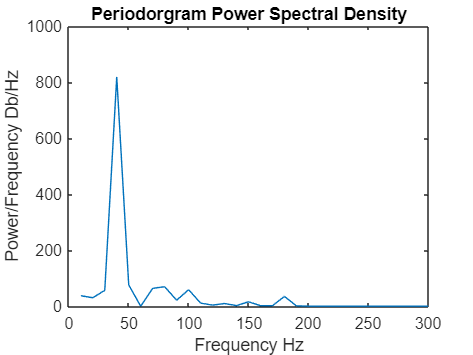

f = 10:10:300; % 300 hundred samples
pxx = periodogram(bl1(:,1,1),[],f,1200);
figure;
plot(f,pxx)
title('Periodorgram Power Spectral Density')
xlabel('Frequency Hz');ylabel('Power/Frequency Db/Hz')

## Channel analisis by Envelope and mean

% Creat each matrix per movement and compute emv
% This matrix takes rest time and movement time therefore 4820
thumb_analisis = zeros(4820,4,trials);
index_analisis = zeros(4820,4,trials);
middle_analisis = zeros(4820,4,trials);
ring_analisis = zeros(4820,4,trials);
pinky_analisis = zeros(4820,4,trials);
hand_analisis = zeros(4820,4,trials);

thumb_count = 0;
index_count = 0;
middle_count = 0;
ring_count = 0;
pinky_count = 0;
hand_count = 0;

% Check the relax marks and check next movement marks
for i=1:length(pks)
    % thumb
    if(pks(i)==1 && pks(i+1)==101)
        thumb_count = thumb_count + 1;
        mov1 = zeros(4820,4);
        mov1(:,1)= emgdata.data(locs(i):locs(i)+4819,2);
        mov1(:,2)= emgdata.data(locs(i):locs(i)+4819,4);
        mov1(:,3)= emgdata.data(locs(i):locs(i)+4819,6);
        mov1(:,4)= emgdata.data(locs(i):locs(i)+4819,8);
        % add the to the figer matrix for further analisis
        thumb_analisis(:,:,thumb_count) = mov1(:,:);

    % index
    elseif(pks(i)==1 && pks(i+1)==102)
        index_count = index_count + 1;
        mov2 = zeros(4820,4);
        mov2(:,1)= emgdata.data(locs(i):locs(i)+4819,2);
        mov2(:,2)= emgdata.data(locs(i):locs(i)+4819,4);
        mov2(:,3)= emgdata.data(locs(i):locs(i)+4819,6);
        mov2(:,4)= emgdata.data(locs(i):locs(i)+4819,8);
        % add the to the figer matrix for further analisis
        index_analisis(:,:,index_count) = mov2(:,:);

    % middle
    elseif(pks(i)==1 && pks(i+1)==103)
        middle_count = middle_count + 1;
        mov3 = zeros(4820,4);
        mov3(:,1)= emgdata.data(locs(i):locs(i)+4819,2);
        mov3(:,2)= emgdata.data(locs(i):locs(i)+4819,4);
        mov3(:,3)= emgdata.data(locs(i):locs(i)+4819,6);
        mov3(:,4)= emgdata.data(locs(i):locs(i)+4819,8);
        % add the to the figer matrix for further analisis
        middle_analisis(:,:,middle_count) = mov3(:,:);

    % ring
    elseif(pks(i)==1 && pks(i+1)==104)
        ring_count = ring_count + 1;
        mov4 = zeros(4820,4);
        mov4(:,1)= emgdata.data(locs(i):locs(i)+4819,2);
        mov4(:,2)= emgdata.data(locs(i):locs(i)+4819,4);
        mov4(:,3)= emgdata.data(locs(i):locs(i)+4819,6);
        mov4(:,4)= emgdata.data(locs(i):locs(i)+4819,8);
        % add the to the figer matrix for further analisis
        ring_analisis(:,:,ring_count) = mov4(:,:);

    % pinky
    elseif(pks(i)==1 && pks(i+1)==105)
        pinky_count = pinky_count + 1;
        mov5 = zeros(4820,4);
        mov5(:,1)= emgdata.data(locs(i):locs(i)+4819,2);
        mov5(:,2)= emgdata.data(locs(i):locs(i)+4819,4);
        mov5(:,3)= emgdata.data(locs(i):locs(i)+4819,6);
        mov5(:,4)= emgdata.data(locs(i):locs(i)+4819,8);
        % add the to the figer matrix for further analisis
        pinky_analisis(:,:,pinky_count) = mov5(:,:);

    % full hand
    elseif(pks(i)==1 && pks(i+1)==106)
        hand_count = hand_count + 1;
        mov6 = zeros(4820,4);
        mov6(:,1)= emgdata.data(locs(i)-200:locs(i)+4619,2);
        mov6(:,2)= emgdata.data(locs(i)-200:locs(i)+4619,4);
        mov6(:,3)= emgdata.data(locs(i)-200:locs(i)+4619,6);
        mov6(:,4)= emgdata.data(locs(i)-200:locs(i)+4619,8);
        % add the to the figer matrix for further analisis
        hand_analisis(:,:,hand_count) = mov6(:,:);

    end
end

% Calculate envelope (peaks) per movement
for i=1:channels
    for j=1:trials
        thumb_analisis(:,i,j) = envelope(thumb_analisis(:,i,j),80,'peaks');
        index_analisis(:,i,j) = envelope(index_analisis(:,i,j),80,'peaks');
        middle_analisis(:,i,j) = envelope(middle_analisis(:,i,j),80,'peaks');
        ring_analisis(:,i,j) = envelope(ring_analisis(:,i,j),80,'peaks');
        pinky_analisis(:,i,j) = envelope(pinky_analisis(:,i,j),80,'peaks');
        hand_analisis(:,i,j) = envelope(hand_analisis(:,i,j),80,'peaks');
    end
end

% % Calculate mean of envelopes
% M1_mean = zeros(4820,4);
% M2_mean = zeros(4820,4);
% M3_mean = zeros(4820,4);
% M4_mean = zeros(4820,4);
% M5_mean = zeros(4820,4);
% M6_mean = zeros(4820,4);
% 
% % Obtain the mean of the envelopes per trial and channel
% for i=1:channels
%     for j=1:trials
%         for k=1:4820
%             M1_mean(k,i) = mean(thumb_analisis(k,i,j));
%             M2_mean(k,i) = mean(index_analisis(k,i,j));
%             M3_mean(k,i) = mean(middle_analisis(k,i,j));
%             M4_mean(k,i) = mean(ring_analisis(k,i,j));
%             M5_mean(k,i) = mean(pinky_analisis(k,i,j));
%             M6_mean(k,i) = mean(hand_analisis(k,i,j));
%         end
%     end
% end

% % Plot MENV for further visual analisis
% figure;
% PlotMENV(M1_mean,M2_mean,M3_mean,M4_mean,M5_mean,M6_mean, ...
%     sujeto)

% % % Plot only first movement MENV and channels
% PlotMENVperMov(M1_mean,1)
% PlotMENVperMov(M2_mean,2)
% PlotMENVperMov(M3_mean,3)
% PlotMENVperMov(M4_mean,4)
% PlotMENVperMov(M5_mean,5)
% PlotMENVperMov(M6_mean,6)

# Feature Extraction

## Create Label Matrix Y(192x1)

% % Label matrix (y) states which movement represents the data
% % This case represents each movement in ascendent order 
% % Classification will be in charge to shuffle the matrix to avoid
% % overfitting
M1 = zeros(trials,1);
M1(:) = 1;
M2 = zeros(trials,1);
M2(:) = 2;
M3 = zeros(trials,1);
M3(:) = 3;
M4 = zeros(trials,1);
M4(:) = 4;
M5 = zeros(trials,1);
M5(:) = 5;
M6 = zeros(trials,1);
M6(:) = 6;
% % Concatenate into a single (y label) matrix and save
y = cat(1,M1,M2,M3,M4,M5,M6);

% y label
twenty = tot_trials*0.2;
eigthy = tot_trials-twenty;
idx1=1;
idx2=trials*0.8;
y_train = zeros(eigthy,1);
movement = 1;
while idx2 <= eigthy
    y_train((idx1:idx2),1) = movement;
    idx1 = idx1 + (trials*0.8);
    idx2 = idx2 + (trials*0.8);
    movement = movement + 1;
end

y_test = zeros(twenty,1);
idx1=1;
idx2=trials*0.2;
movement = 1;
while idx2 <= twenty
    y_test((idx1:idx2),1) = movement;
    idx1 = idx1 + (trials*0.2);
    idx2 = idx2 + (trials*0.2);
    movement = movement + 1;
end

% % y label
% y_train = zeros(tot_trails,1);
% y_train((1:32),1) = 1;
% y_train((33:64),1) = 2;
% y_train((65:96),1) = 3;
% y_train((97:128),1) = 4;
% y_train((129:160),1) = 5;
% y_train((161:192),1) = 6;

% y_test = zeros(48,1);
% y_test((1:8),1) = 1;
% y_test((9:16),1) = 2;
% y_test((17:24),1) = 3;
% y_test((25:32),1) = 4;
% y_test((33:40),1) = 5;
% y_test((41:48),1) = 6;

savelocation = strcat('SxxAll','/',sujeto,'y.mat');
save(savelocation,"y");
savelocation = strcat(sujeto,'/',sujeto,'y_train.mat');
save(savelocation,"y_train");
savelocation = strcat(sujeto,'/',sujeto,'y_test.mat');
save(savelocation,"y_test");

## Create Characteristics Matrix X(240x4x12)

## Time Domain Analisis

% Number of characteristics
n = 10;
% Characterisitcs Matrix trial x channel x characteristics
X = zeros(tot_trials,4,n);

% Compute the characterisits for further analisis and add them to matrix X
% EMV
%X(:,:,1) = cat(1,thumb_emv,index_emv,middle_emv,ring_emv,pinky_emv,hand_emv);
% RMS
X(:,:,1) = cat(1,thumb_rms,index_rms,middle_rms,ring_rms,pinky_rms,hand_rms);
% % STD
X(:,:,2) = cat(1,thumb_std,index_std,middle_std,ring_std,pinky_std,hand_std);
% VAR
X(:,:,3) = cat(1,thumb_var,index_var,middle_var,ring_var,pinky_var,hand_var);
% MAV
X(:,:,4) = cat(1,thumb_mav,index_mav,middle_mav,ring_mav,pinky_mav,hand_mav);
% AUC
%X(:,:,6) = cat(1,thumb_auc,index_auc,middle_auc,ring_auc,pinky_auc,hand_auc);
% IEMG
X(:,:,5) = cat(1,thumb_iemg,index_iemg,middle_iemg,ring_iemg,pinky_iemg,hand_iemg);
% LOGD
X(:,:,6) = cat(1,thumb_logd,index_logd,middle_logd,ring_logd,pinky_logd,hand_logd);
% ZCR
X(:,:,7) = cat(1,thumb_zcr,index_zcr,middle_zcr,ring_zcr,pinky_zcr,hand_zcr);
% WFL
X(:,:,8) = cat(1,thumb_wfl,index_wfl,middle_wfl,ring_wfl,pinky_wfl,hand_wfl);
% SSI
X(:,:,9) = cat(1,thumb_ssi,index_ssi,middle_ssi,ring_ssi,pinky_ssi,hand_ssi);
% WEN
X(:,:,10) = cat(1,thumb_wen,index_wen,middle_wen,ring_wen,pinky_wen,hand_wen);

% savelocation = strcat(sujeto,'/',sujeto,'X_features.mat');
% save(savelocation,"X");

## Classification matrixes TD and FD

% X matrix per total of trials fro, TD features
features_num = 40;
X_1 = zeros(tot_trials,features_num);

% X_1 represents time-domain characterisitics 
% Each movement has 48 characterisitics in total
% 4 channels * 12 characteristics = 48 characteristics
for i=1:tot_trials
    feature = zeros(1,features_num);
    
    feature(1:10) = X(i,1,:);
    feature(11:20) = X(i,2,:);
    feature(21:30) = X(i,3,:);
    feature(31:40) = X(i,4,:);
    
    % Add them to TD matrix
    X_1(i,:) = feature;
end

## FD Matrix


% Resize X_2
% X_2 = (192x120)
% Compute periodorgam and fill features matrix
bl_mat = cat(3,bl1,bl2,bl3,bl4,bl5,bl6);
% 4 channels * 30 characteristics = 120 characteristics
X_2 = zeros(tot_trials,120);
f = 10:10:600; % Get 600 samples

% Go over the trial, compute PSD and add them per channel to the 
% X matrix
for i=1:tot_trials
    % PSD of the first channel, 300 samples
    feature = zeros(1,120);
    pxx1 = periodogram(bl_mat(:,1,i),[],f,1200);
    pxx1 = pxx1(:,(1:end/2)); % Save into mat half the samples
    feature(1:30) = pxx1;
    
    % PSD of the second channel, 300 samples
    pxx2 = periodogram(bl_mat(:,2,i),[],f,1200);
    pxx2 = pxx2(:,(1:end/2)); % Save into mat half the samples
    feature(31:60) = pxx2;
    
    % PSD of the third channel, 300 samples
    pxx3 = periodogram(bl_mat(:,3,i),[],f,1200);   
    pxx3 = pxx3(:,(1:end/2)); % Save into mat half the samples
    feature(61:90) = pxx3;
    
    % PSD of the fourth channel, 300 samples
    pxx4 = periodogram(bl_mat(:,4,i),[],f,1200);
    pxx4 = pxx4(:,(1:end/2)); % Save into mat half the samples
    feature(91:120) = pxx4;
    
    % Add them to FD matrix
    X_2(i,:) = feature;
end

% Save the matrix for further analisis in another computer if needed
savelocation = strcat('SxxAll','/',sujeto,'X_1.mat');
save(savelocation,"X_1");
savelocation = strcat(sujeto,'/',sujeto,'X_2.mat');
save(savelocation,"X_2");

## Proportion 80-20 (X_train, X_test)

X_train = zeros(eigthy,40);
idx1=1;
idx2=trials*0.8;
idx3=1;
idx4 = trials*0.8;

% X_train
while idx1 <= eigthy
    X_train((idx1:idx2),:) = X_1((idx3:idx4),:);
    idx1 = idx1 + (trials*0.8);
    idx2 = idx2 + (trials*0.8);
    idx3 = idx3 + trials;
    idx4 = idx4 + trials;
end

X_test = zeros(twenty,40);
idx1=1;
idx2=trials*0.2;
idx3=1;
idx4 = trials*0.2;
% X_test
while idx1 <= twenty
    X_test((idx1:idx2),:) = X_1((idx3:idx4),:);
    idx1 = idx1 + (trials*0.2);
    idx2 = idx2 + (trials*0.2);
    idx3 = idx3 + trials;
    idx4 = idx4 + trials;
end

savelocation = strcat(sujeto,'/',sujeto,'x_train.mat');
save(savelocation,"X_train");
savelocation = strcat(sujeto,'/',sujeto,'x_test.mat');
save(savelocation,"X_test");

For X_2

X2_train = zeros(eigthy,120);
idx1=1;
idx2=trials*0.8;
idx3=1;
idx4 = trials*0.8;

% X_train
while idx1 <= eigthy
    X2_train((idx1:idx2),:) = X_2((idx3:idx4),:);
    idx1 = idx1 + (trials*0.8);
    idx2 = idx2 + (trials*0.8);
    idx3 = idx3 + trials;
    idx4 = idx4 + trials;
end

X2_test = zeros(twenty,120);
idx1=1;
idx2=trials*0.2;
idx3=1;
idx4 = trials*0.2;
% X_test
while idx1 <= twenty
    X2_test((idx1:idx2),:) = X_2((idx3:idx4),:);
    idx1 = idx1 + (trials*0.2);
    idx2 = idx2 + (trials*0.2);
    idx3 = idx3 + trials;
    idx4 = idx4 + trials;
end

% savelocation = strcat(sujeto,'/',sujeto,'x_train.mat');
% save(savelocation,"X2_train");
% savelocation = strcat(sujeto,'/',sujeto,'x_test.mat');
% save(savelocation,"X2_test");

## Analize and Create Model

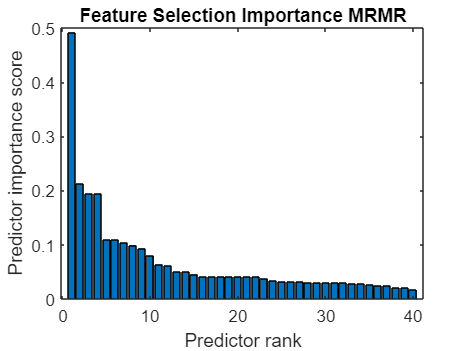

% https://la.mathworks.com/help/stats/classification-model-building-and-assessment.html?s_tid=CRUX_lftnav
[idx, scores] = fscmrmr(X_1,y); % Value of the characteristics
figure;
bar(scores(idx(1:40))) % Plot top 10 characteristis by their importance
title('Feature Selection Importance MRMR')
xlabel('Predictor rank')
ylabel('Predictor importance score')


disp('Top 10 predictors:')

Top 10 predictors:


disp(idx(1:10))

    40     7    10    37    25    27    18    38     8    34




return

## Call Classification Learner

% We use: 12,24,36,48 features to analize and obtain the best model
% LDA
% Quadratic SVM or Linear SVM (Analize best model)
% Wide NN

classificationLearner(X_1,y,'CrossVal','on','KFold',5);

% Export the model before running next sections
% Comment "return" and run after having the model in the workspace
% Don't forget to name the model "model" 
return

## Make predictions

% To make predictions on a new predictor column matrix, X, 
% use:yfit = c.predictFcn(X) replacing 'c' 
% with the name of the variable that is this struct, 
% e.g. 'trainedModel'. 
% X must contain exactly 48 columns 
% because this model was trained using 48 predictors. 
% X must contain only predictor columns in exactly the same order and format as your 
% training data. Do not include the response column or 
% any columns you did not import into the app.  
% For more information, see How to predict using an exported model.
true = 0;
g1 = zeros(1,twenty);
g2 = zeros(1,twenty);
wheretrial = twenty/6;
acc = 0;
for i=1:twenty

    %r = randi([1 48],1,1);
%     fprintf('Trial %i\n',i)

    % Check how predictFCN works
    yfit = model.predictFcn((X_test(i,:)));

    if(i <= wheretrial)
        g1(i) = 1;
        g2(i) = yfit;
%         disp('Should be 1')
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    elseif(i>wheretrial && i<=2*wheretrial)
        g1(i) = 2;
        g2(i) = yfit;
%         disp('Should be 2')
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    elseif(i>2*wheretrial && i<=3*wheretrial)
        g1(i) = 3;
        g2(i) = yfit;
%         disp('Should be 3')
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    elseif(i>3*wheretrial && i<=4*wheretrial)
        g1(i) = 4;
        g2(i) = yfit;g2(i) = yfit;
%         disp('Should be 4')
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    elseif(i>4*wheretrial && i<=5*wheretrial)
        g1(i) = 5;
        g2(i) = yfit;
%         disp('Should be 5')
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    elseif(i>5*wheretrial)
        g1(i) = 6;
        g2(i) = yfit;
%         disp('Should be 6')
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    end
    
%     fprintf('Predicted %i\n',yfit)

end

acc = true/twenty;
fprintf('Test accuracy %2f\n',acc)
C = confusionmat(g1,g2);

h = figure(2);
confusionchart(C)

savelocation = strcat(sujeto,'/','CM','.png');
exportgraphics(h,savelocation)

## DMNN Testing

## Convert matrix into requiered matrix form

X = cat(2,X_train,y_train);
M = 1;

## Train DMNN

[weights, classifiedExamples] = trainDMNN(X,M);

true = 0;
g1 = zeros(1,twenty);
g2 = zeros(1,twenty);
wheretrial = twenty/6;
acc = 0;
for i=1:twenty

    %r = randi([1 48],1,1);
%     fprintf('Trial %i\n',i)

    output = predictDMNN(X_test(i,:),weights);
    yfit = find(output);

    if(i <= wheretrial)
        g1(i) = 1;
        g2(i) = yfit;
%         disp('Should be 1')
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    elseif(i>wheretrial && i<=2*wheretrial)
        g1(i) = 2;
        g2(i) = yfit;
%         disp('Should be 2')
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    elseif(i>2*wheretrial && i<=3*wheretrial)
        g1(i) = 3;
        g2(i) = yfit;
%         disp('Should be 3')
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    elseif(i>3*wheretrial && i<=4*wheretrial)
        g1(i) = 4;
        g2(i) = yfit;g2(i) = yfit;
%         disp('Should be 4')
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    elseif(i>4*wheretrial && i<=5*wheretrial)
        g1(i) = 5;
        g2(i) = yfit;
%         disp('Should be 5')
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    elseif(i>5*wheretrial)
        g1(i) = 6;
        g2(i) = yfit;
%         disp('Should be 6')
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    end
    
%     fprintf('Predicted %i\n',yfit)

end

acc = true/twenty;
fprintf('Test accuracy %2f\n',acc)
figure;
C = confusionchart(g1,g2, ...
    'Title','All vs 1', ...
    'RowSummary','row-normalized');

h = figure(2);
confusionchart(C)

savelocation = strcat(sujeto,'/','CM','.png');
exportgraphics(h,savelocation)

y = [];
for i=1:tot_trials/6
    for j=1:6
        y(end+1) = j;
    end
end
y = transpose(y);
